# **Examen parcial 1: Control y Sistemas 2025**

## **Requerimientos de Ingeniería**

Se recuperan las señales de dos sensores x_c(t) y x_r(t). La primera es una onda senoidal y la segunda una onda rectangular. Ambas fueron tratadas con un filtro antialiasing pero las mismas acarrean unas perturbaciones particulares que se quieren remover. Debemos realizar el tratamiento correspondiente con el método oversampling para lograr ingresarlas a un sistema de cómputo discreto (procesador, DSP) donde se desea realizar operaciones con la información que traen. Para ello es necesario asegurarse de remover el ruido que tienen y hacerlo logrando mantener la forma de la onda, acotar el desfasaje del resultado y tener una buena relación ruido-señal. Buscamos que el procesador realice los cálculos confiando que la señales que proveemos traen la información real.   

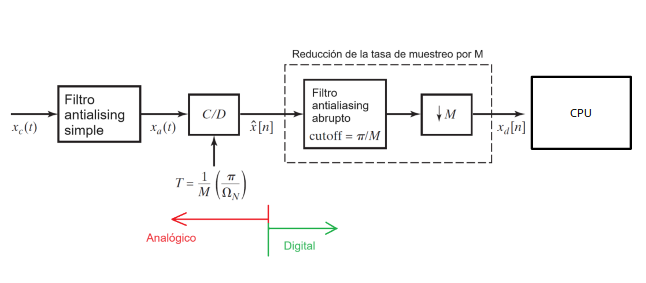

## **Antes de iniciar los cálculos y el diseño**

Describa lo que interpreta del requerimiento de la aplicación y cómo procederá para resolver reducido a tres simples pasos de manera descriptiva y simple.  

- **Defino banda y factor M: **Mido la banda útil de cada señal y elijo un oversampling (p.ej. 8×) que aleje el aliasing y aporte ≈ 3 dB de SNR por duplicar Fs.

- **Muestreo y filtrado a Fs·M: **Muestreo con ADC de N bits y, ya en digital a Fs·M, aplico un FIR lineal-fase (o IIR suave si necesito menos cómputo) para atenuar el ruido sin distorsionar la forma ni el desfase.

- **Decimación y chequeo final: **Bajo la tasa a Fs con un decimador, reviso SNR y retardo; si no se cumplen las metas ajusto la longitud/orden del filtro. Confirmo que en punto fijo no haya overflow y entrego las señales limpias al DSP.

## Descripción de las señales

Una de las señales tiene una frecuencia máxima de 1 Hz, la otra de 5Hz; y se desea usar un filtro antialiasing analógico **simple** [con atenuación de -3 dB en 100 Hz y -60 dB en 200 Hz (no es necesario diseñar este filtro analógico)]. 

Ambas señales son interferidas por ruidos distintos. La señal senoidal acarrea una componente de ruido senoidal del 50Hz. En cambio la señal rectangular es atacada por un ruido gaussiano tal que la relación señal-ruido entre la señal rectangular y el ruido es de 15dB.

clc
clear
close all
%% Frecuencia de signals
frequency_xc = 1;        % [Hz] frequency of signal 1
frequency_xr = 5;       % [Hz] frequency of signal 2
frequency_noise = 50      % [Hz]

frequency_noise = 50

% Definir SNR ruido onda rectangular (en dB)
SNR_dB = 1;

## Muestreo y señales

## Determine la mínima frecuencia de muestreo

Necesitamos que la etapa de muestreo evite errores por aliasing y que podamos recuperar la información que tiene la señal.

La señal rectangular solo necesita hasta la quinta armónica 5Hz*5=25Hz, el diltro analógico deja pasar energía hasta 200Hz con buena atenuación. para evitar el aliasing consideramos fmax=200Hz


$$\mathrm{fs}>2\mathrm{fmax}->\mathrm{fs}>2*200\mathrm{Hz}=400\mathrm{Hz}$$


## Declaración de parámetros de muestreo

## Parámetros de las señal

sampling_rate = 2*200;       % [Hz] how often the signal is sampled
fs = sampling_rate

fs = 400

## Rango de tiempo y vector de tiempo

start_time = 0;         % [s] beginning of the time window
end_time = 1;         % [s] end of the time window

t = start_time : 1/sampling_rate : end_time;  % [s] time points at which the signal is sampled

## Construcción de las señales y ruidos

## Señal 1, señal 2 y ruidos

Construya usando su vector de tiempo las señales senoidales y rectangular. Construya los ruidos y apliquelos a las señales originales.


% 2π * frequency [rad/s] * time [s] → [rad] → sin(...) → unitless amplitude
signal_xc = sin(2 * pi * frequency_xc * t);         % [1] sine wave values (unitless amplitude)
signal_xr = square(2 * pi * frequency_xr * t);

% ruido_xc y ruido_xr
noise_xc     = sin(2*pi*frequency_noise * t);  % interferencia senoidal 50 Hz
sigma        = 1 / (10^(SNR_dB/20));          % desviación estándar del ruido
noise_xr     = sigma * randn(size(t));  

% Calcular 
signal_noise_xc = signal_xc + noise_xc;        % [1] signal with additional noise
signal_noise_xr = signal_xr + noise_xr;	    % [1] signal with additional noise


## Plot de señales en el dominio del tiempo

Realice un plot de la señales sin la perturbación, el ruido y la señal con la perturbación agregada. 

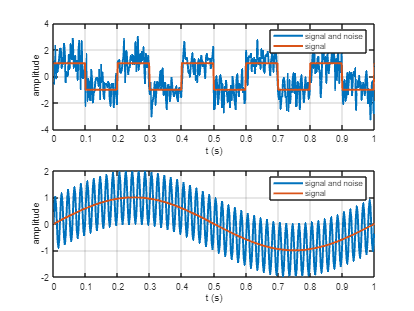

figure
hold on
subplot(2,1,1)
plot(t, [signal_noise_xr; signal_xr], 'linewidth', 2)
xlabel('t (s)')
ylabel('amplitude')
legend('signal and noise', 'signal')
grid on
subplot(2,1,2)
plot(t, [signal_noise_xc; signal_xc], 'linewidth', 2)
xlabel('t (s)')
ylabel('amplitude')
legend('signal and noise', 'signal')
grid on

## Plot de señales en el dominio de la frecuencia

Realice un plot de la señales sin la perturbación agregada en el dominio de la frecuencia para lograr ver sus componentes. 

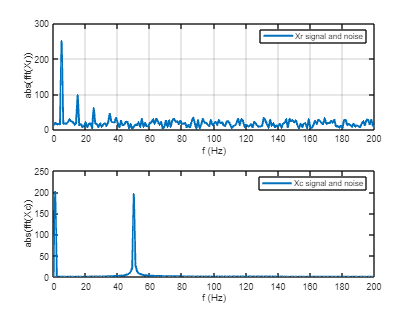

Xr = abs(fft(signal_noise_xr));
Xc = abs(fft(signal_noise_xc));
figure
subplot(2,1,1)
plot(linspace(0, fs/2, round(length(Xr)/2)), Xr(1:round(length(Xr)/2)), 'linewidth', 2);
xlabel('f (Hz)')
ylabel('abs(fft(Xr))')
legend('Xr signal and noise')
grid on
subplot(2,1,2)
plot(linspace(0, fs/2, round(length(Xc)/2)), Xc(1:round(length(Xc)/2)), 'linewidth', 2);
xlabel('f (Hz)')
ylabel('abs(fft(Xc))')
legend('Xc signal and noise')

## Conclusiones

***La señal tiene más información representada en el dominio del tiempo y o de la frecuencia?***

    La mayor parte de la información necesaria para el diseño de filtros aparece en el dominio de la frecuencia: ahí vemos exactamente en qué bandas se concentra la señal útil (armónicos de la cuadrada, el pico de 1 Hz) y dónde está el ruido (piso espectral y pico en 50 Hz). El dominio del tiempo, en cambio, nos muestra la forma de onda, transitorios y el desfase introducido, pero no nos muestra directamente la localización espectral del ruido.

*** Esto puede influir en la elección del filtro?***

   Como necesitamos atenuar selectivamente las componentes de ruido (por ejemplo 50 Hz o fuera de banda de la cuadrada) sin afectar la señal útil, el análisis en frecuencia es muy importante para definir las bandas de paso y rechazo. Pero, para garantizar mínima distorsión temporal  y conservar la forma de onda, también debemos considerar en el diseño la respuesta en el tiempo, lo que nos lleva a eleguir filtros FIR de fase lineal o estructuras IIR con compensación de fase.

## Filtrado y Decimación

## Las características del decimador y del filtro digital que debe implementar

Deberá elegir entre alguna de las implementaciones de filtros posibles. Fundamente porque realizó dicha elección.

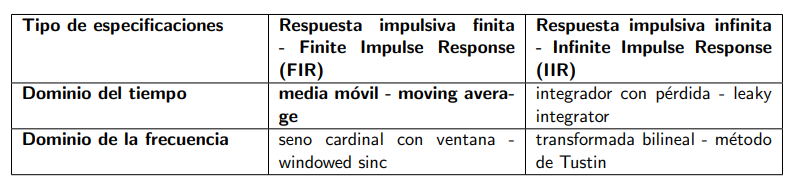

**Decimación: ** Elijo bajar de F_s = 200Hz a F_sfinal = 20Hz -> D = 10

Elijo un fuiltro FIR de fase lineal de orden N=15 con corte en: Fc = F_sfinal / 2 = 10Hz 

para atenuar >= 60dB todas las componentes por arriba de 10 Hz antes de decimar.

## Diseño del filtro FIR onda senoidal



% Parámetros
Fs       = sampling_rate;       % 200 Hz
Fc       = 10;                  % Corte en 10 Hz (dejamos pasar 1 Hz y aplacamos 50 Hz)
N        = 15;                 % Orden del filtro (par para Blackman)
Fc_norm  = Fc/(Fs/2);           % Normalizada (0–1)

% Diseño FIR Blackman
b = fir1(N, Fc_norm, blackman(N+1));
a = 1;

% Filtrado
filtered_signal_xc = filter(b, a, signal_noise_xc);





## Polos, ceros y diagrama de bode

Realice un plot para ver ceros, polos y el diagrama de bode del filtro

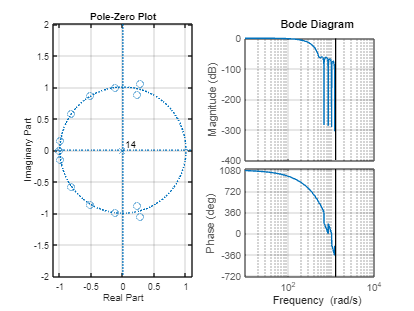

figure
subplot(1,2,1)
zplane(b,a)
grid on
subplot(1,2,2)
bode(filt(b, a, 1/sampling_rate))
grid on

## Decimación onda senoidal

Realice una decimación de la onda filtrada, elegiendo bien la nueva frecuencia de muestreo.

fs     = sampling_rate;  
fs_new = 20;             
D = round(fs/fs_new);    

subsampled_filt_signal_xc = filtered_signal_xc(1:D:end);
subsampled_t             = t(1:D:end);


## Análisis en frecuencia y tiempo onda senoidal

Haga un plot en frecuencia de para ver si eliminó las componentes que buscaba eliminar. 

## Código análisis en frecuencia

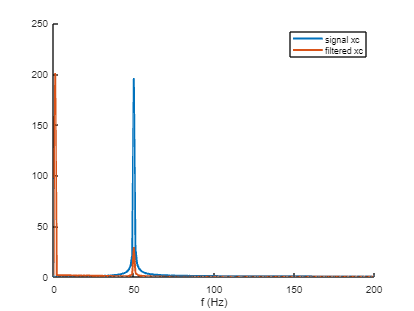


X = abs(fft(signal_noise_xc));
X_filt = abs(fft(filtered_signal_xc));
figure
hold on
plot(linspace(0, fs/2, round(length(X)/2)), X(1:round(length(X)/2)), 'linewidth', 2);
plot(linspace(0, fs/2, round(length(X_filt)/2)), X_filt(1:round(length(X_filt)/2)), 'linewidth', 2);
legend('signal xc', 'filtered xc')
xlabel('f (Hz)')

## Código análisis en tiempo

Grafique la señal original, la que tiene ruido y la filtrada para ver una compararción. La señal filtrada tiene mucho desfasaje? en tiempo o en forma? Explique

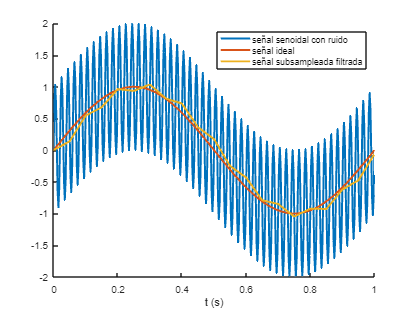

figure
hold on
plot(t, [signal_noise_xc; signal_xc], 'linewidth', 2)
plot(subsampled_t, subsampled_filt_signal_xc, 'linewidth', 2)
xlabel('t (s)')
legend('señal senoidal con ruido', 'señal ideal', 'señal subsampleada filtrada')

## Cálculo de SNR para score del filtro de onda senoidal

subsampled_signal_xc = signal_xc(1:round(fs/fs_new):end);
SNR_xc = 20*log10(rms(subsampled_signal_xc)/rms(subsampled_filt_signal_xc - subsampled_signal_xc))

SNR_xc = 16.9249

if SNR_xc < 10
    disp(['Nota Ej 1 = 4'])
elseif SNR_xc < 13
    disp(['Nota Ej 1 = 5'])
elseif SNR_xc < 16
    disp(['Nota Ej 1 = 6'])
elseif SNR_xc < 19
    disp(['Nota Ej 1 = 7'])
elseif SNR_xc < 22
    disp(['Nota Ej 1 = 8'])
else
    disp(['Nota Ej 1 = 9'])
end

Nota Ej 1 = 7


## Resultados onda senoidal

*** ¿La señal filtrada tiene mucho desfasaje? ¿distorsiona la forma? Explique sus resultados***

**Retardo (desfase) constante**

Al usar un FIR de orden N=15 

Ese desplazamiento aparece en la curva amarilla respecto de la naranja: toda la señal se retrasa ~0,0375 s.

**Distorsión de forma**

Con solo 15 taps la transición desde 1 Hz hasta 10 Hz es muy suave, por lo que:

La envolvente de 1 Hz **se atenúa ligeramente** y sus crestas se redondean un poco.

La componente de 50 Hz se reduce, pero no tanto como con un filtro de orden mayor (queda algo de remanente).

## Diseño del filtro FIR onda cuadrada


% Parámetros
Fs    = sampling_rate;    
Fp    = 25;               
Fs2   = 30;               
N2    = 100;              
Wn    = [0 Fp Fs2 Fs/2]/(Fs/2);



b = firpm(N2, Wn, [1 1 0 0]);
a = 1;


filtered_signal_xr = filter(b, a, signal_noise_xr);



## Polos, ceros y diagrama de bode

Realice un plot para ver ceros, polos y el diagrama de bode del filtro

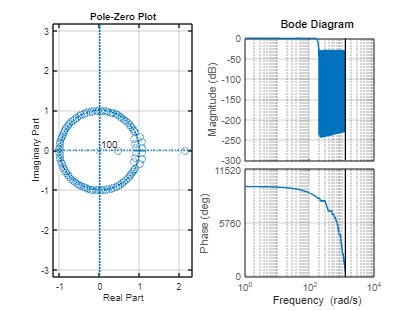

figure
subplot(1,2,1)
zplane(b,a)
grid on
subplot(1,2,2)
bode(filt(b, a, 1/sampling_rate))
grid on

## Decimación onda cuadrada

Realice una decimación de la onda filtrada, elegiendo bien la nueva frecuencia de muestreo.

subsampled_filt_signal_xr = filtered_signal_xr(1:round(fs/fs_new):end);

## Análisis en frecuencia y tiempo onda cuadrada

Haga un plot en frecuencia de para ver si eliminó las componentes que buscaba eliminar. 

## Código análisis en frecuencia

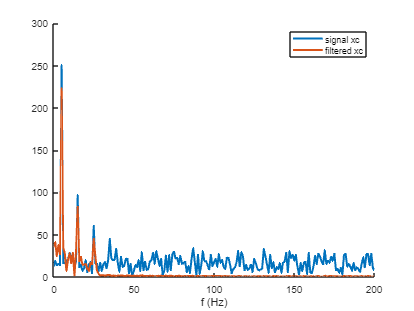

X = abs(fft(signal_noise_xr));
X_filt = abs(fft(filtered_signal_xr));
figure
hold on
plot(linspace(0, fs/2, round(length(X)/2)), X(1:round(length(X)/2)), 'linewidth', 2);
plot(linspace(0, fs/2, round(length(X_filt)/2)), X_filt(1:round(length(X_filt)/2)), 'linewidth', 2);
legend('signal xc', 'filtered xc')
xlabel('f (Hz)')

## Código análisis en tiempo

Grafique la señal original, la que tiene ruido y la filtrada para ver una compararción. 

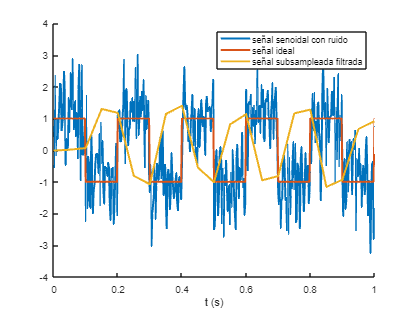

figure
hold on
plot(t, [signal_noise_xr; signal_xr], 'linewidth', 2)
plot(subsampled_t, subsampled_filt_signal_xr, 'linewidth', 2)
xlabel('t (s)')
legend('señal senoidal con ruido', 'señal ideal', 'señal subsampleada filtrada')

subsampled_signal_xr = signal_xr(1:round(fs/fs_new):end);
SNR_xr = 20*log10(rms(subsampled_signal_xr)/rms(subsampled_filt_signal_xr - subsampled_signal_xr))

SNR_xr = -2.6048

if SNR_xr < 10
    disp(['Nota Ej 1 = 4'])
elseif SNR_xr < 13
    disp(['Nota Ej 1 = 5'])
elseif SNR_xr < 16
    disp(['Nota Ej 1 = 6'])
elseif SNR_xr < 19
    disp(['Nota Ej 1 = 7'])
elseif SNR_xr < 22
    disp(['Nota Ej 1 = 8'])
else
    disp(['Nota Ej 1 = 9'])
end

Nota Ej 1 = 4


## Resultados onda senoidal

*** ¿La señal filtrada tiene mucho desfasaje? ¿distorsiona la forma? Explique sus resultados.***

## ADC

***¿Cuántos bits tendría que tener el ADC de cada canal en función del ruido observado suponiendo 1 bit de guarda para el ruido?***

## Análisis de aritmética punto fijo o flotante 

***Sugiera una representación en punto fijo que sea óptima para almacenar la señal senoidal, sin la presencia del ruido.***

## `Elegir `una` opción`

***Teniendo toda la información reunida hasta ahora, ¿qué representación usaría para el diseño del filtro para optimizar recursos?***